# Machine Learning Online Class

## Initialization

clear ; close all; clc

## =========== Part 1: Loading and Visualizing Data =============

% Load Training Data
fprintf('Loading and Visualizing Data ...\n')

Loading and Visualizing Data ...


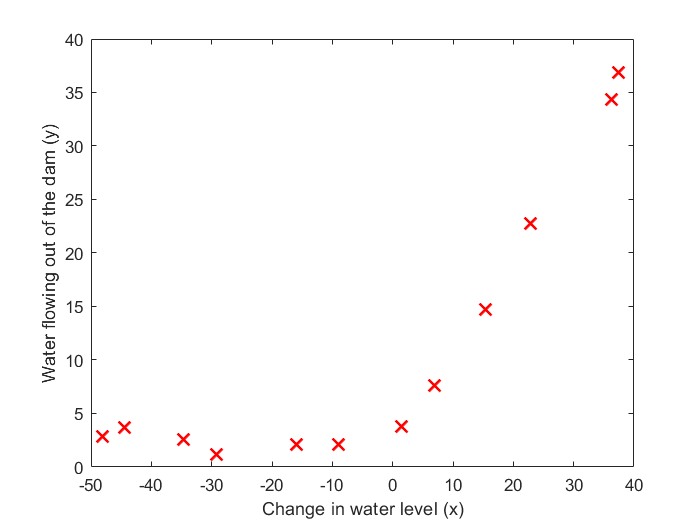


% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment
load ('ex5data1.mat');

% m = Number of examples
m = size(X, 1);

% Plot training data
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 2: Regularized Linear Regression Cost =============

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);

fprintf(['Cost at theta = [1 ; 1]: %f '...
         '\n(this value should be about 303.993192)\n'], J);

Cost at theta = [1 ; 1]: 303.993192 
(this value should be about 303.993192)



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 3: Regularized Linear Regression Gradient =============

theta = [1 ; 1];
[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);

fprintf(['Gradient at theta = [1 ; 1]:  [%f; %f] '...
         '\n(this value should be about [-15.303016; 598.250744])\n'], ...
         grad(1), grad(2));

Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 
(this value should be about [-15.303016; 598.250744])



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 4: Train Linear Regression =============

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01
Iteration     3 | Cost: 2.237391e+01


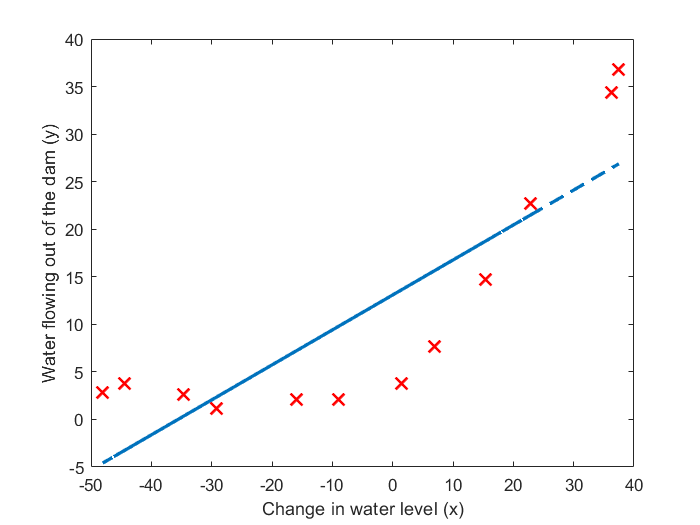


%  Plot fit over the data
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 5: Learning Curve for Linear Regression =============

lambda = 0;
[error_train, error_val] = ...
    learningCurve([ones(m, 1) X], y, ...
                  [ones(size(Xval, 1), 1) Xval], yval, ...
                  lambda);

Iteration     1 | Cost: 3.628289e-04
Iteration     2 | Cost: 2.199486e-05
Iteration     3 | Cost: 4.157539e-09
Iteration     4 | Cost: 4.291129e-10
Iteration     5 | Cost: 1.297070e-11
Iteration     6 | Cost: 1.071136e-13
Iteration     7 | Cost: 1.418182e-15
Iteration     8 | Cost: 3.096638e-17
Iteration     9 | Cost: 6.236430e-18
Iteration    10 | Cost: 1.643627e-19
Iteration    11 | Cost: 1.515726e-21
Iteration    12 | Cost: 2.435846e-23
Iteration    13 | Cost: 4.257960e-25
Iteration    14 | Cost: 1.320908e-26
Iteration    15 | Cost: 2.666350e-28
Iteration    16 | Cost: 5.679799e-29
Iteration    17 | Cost: 2.465190e-30
Iteration    18 | Cost: 9.860761e-32
Iteration    19 | Cost: 0.000000e+00
Iteration     1 | Cost: 4.282328e-01
Iteration     2 | Cost: 8.295365e-30
Iteration     3 | Cost: 4.930381e-32
Iteration     1 | Cost: 1.021540e+02
Iteration     2 | Cost: 3.286595e+00
Iteration     3 | Cost: 3.286595e+00
Iteration     1 | Cost: 1.438726e+02
Iteration     2 | Cost: 1.035224e+02
I

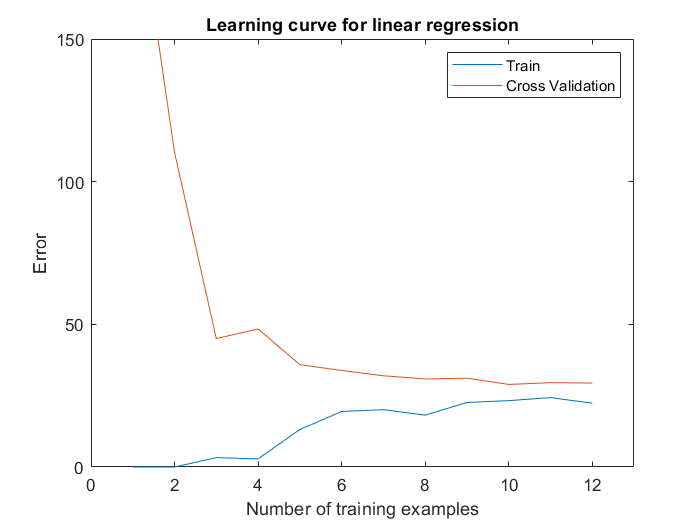


plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])


fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	210.522449
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 6: Feature Mapping for Polynomial Regression =============

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = bsxfun(@minus, X_poly_test, mu);
X_poly_test = bsxfun(@rdivide, X_poly_test, sigma);
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = bsxfun(@minus, X_poly_val, mu);
X_poly_val = bsxfun(@rdivide, X_poly_val, sigma);
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## =========== Part 7: Learning Curve for Polynomial Regression =============

lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.411783e-01
Iteration    11 | Cost: 8.015003e-01
Iteration    12 | Cost: 7.608604e-01
Iteration    13 | Cost: 6.730405e-01
Iteration    14 | Cost: 4.871409e-01
Iteration    15 | Cost: 4.430559e-01
Iteration    16 | Cost: 4.403831e-01
Iteration    17 | Cost: 4.316665e-01
Iteration    18 | Cost: 4.220671e-01
Iteration    19 | Cost: 4.161135e-01
Iteration    20 | Cost: 4.061901e-01
Iteration    21 | Cost: 3.796860e-01
Iteration    22 | Cost: 3.520089e-01
Iteration    23 | Cost: 3.362824e-01
Iteration    24 | Cost: 3.275295e-01
Iteration    25 | Cost: 3.256200e-01
Iteration    26 | Cost: 3.240619e-01
Iteration    27 | Cost: 3.232711e-01
I


% Plot training data and fit
figure(1);
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));

figure(2);
[error_train, error_val] = ...
    learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 2.865325e-01
Iteration     2 | Cost: 1.896079e-03
Iteration     3 | Cost: 5.614798e-08
Iteration     4 | Cost: 6.250433e-09
Iteration     5 | Cost: 1.771778e-10
Iteration     6 | Cost: 5.404078e-12
Iteration     7 | Cost: 3.142740e-13
Iteration     8 | Cost: 2.182675e-15
Iteration     9 | Cost: 2.113504e-16
Iteration    10 | Cost: 2.257217e-18
Iteration    11 | Cost: 2.888868e-19
Iteration    12 | Cost: 1.569607e-20
Iteration    13 | Cost: 1.041607e-22
Iteration    14 | Cost: 6.919703e-24
Iteration    15 | Cost: 1.431398e-26
Iteration    16 | Cost: 1.797124e-27
Iteration    17 | Cost: 8.874685e-29
Iteration    18 | Cost: 9.860761e-32
Iteration    19 | Cost: 0.000000e+00
Iteration     1 | Cost: 5.373343e-02
Iteration     2 | Cost: 2.656989e-04
Iteration     3 | Cost: 1.480972e-05
Iteration     4 | Cost: 1.880576e-10
Iteration     5 | Cost: 1.880553e-10
Iteration     6 | Cost: 9.442954e-11
Iteration     7 | Cost: 6.841388e-15
Iteration     8 | Cost: 6.840914e-15
I

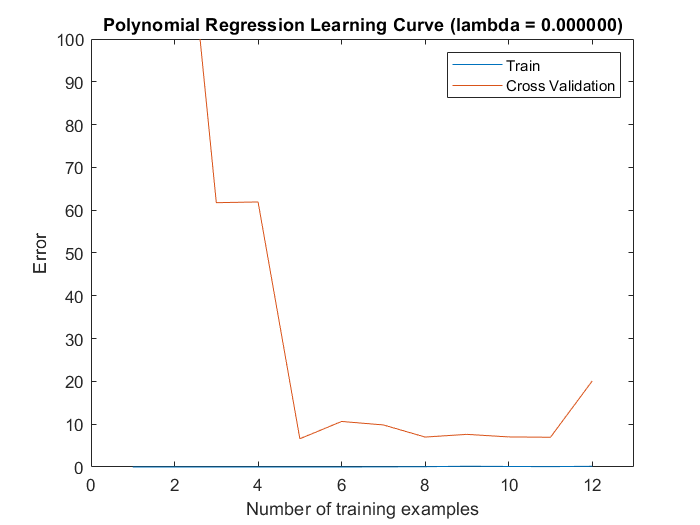

plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')


fprintf('Polynomial Regression (lambda = %f)\n\n', lambda);

Polynomial Regression (lambda = 0.000000)



fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	331.806752
  	2		0.000000	160.121510
  	3		0.000000	61.754825
  	4		0.000000	61.928895
  	5		0.000000	6.598805
  	6		0.000000	10.639200
  	7		0.030283	9.827380
  	8		0.069787	6.997780
  	9		0.180103	7.626238
  	10		0.123965	7.027225
  	11		0.082809	6.950743
  	12		0.167414	20.104369



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 8: Validation for Selecting Lambda =============

[lambda_vec, error_train, error_val] = ...
    validationCurve(X_poly, y, X_poly_val, yval);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.411783e-01
Iteration    11 | Cost: 8.015003e-01
Iteration    12 | Cost: 7.608604e-01
Iteration    13 | Cost: 6.730405e-01
Iteration    14 | Cost: 4.871409e-01
Iteration    15 | Cost: 4.430559e-01
Iteration    16 | Cost: 4.403831e-01
Iteration    17 | Cost: 4.316665e-01
Iteration    18 | Cost: 4.220671e-01
Iteration    19 | Cost: 4.161135e-01
Iteration    20 | Cost: 4.061901e-01
Iteration    21 | Cost: 3.796860e-01
Iteration    22 | Cost: 3.520089e-01
Iteration    23 | Cost: 3.362824e-01
Iteration    24 | Cost: 3.275295e-01
Iteration    25 | Cost: 3.256200e-01
Iteration    26 | Cost: 3.240619e-01
Iteration    27 | Cost: 3.232711e-01
I

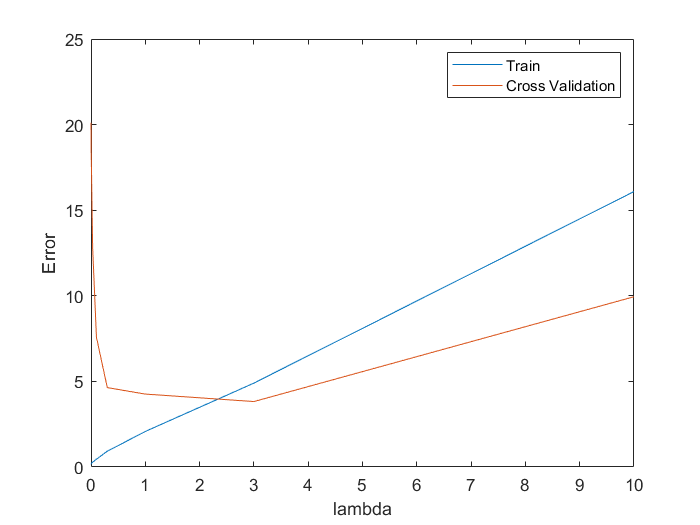


close all;
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');


fprintf('lambda\t\tTrain Error\tValidation Error\n');

lambda		Train Error	Validation Error


for i = 1:length(lambda_vec)
	fprintf(' %f\t%f\t%f\n', ...
            lambda_vec(i), error_train(i), error_val(i));
end

 0.000000	0.167414	20.104369
 0.001000	0.162623	19.742498
 0.003000	0.182192	18.436621
 0.010000	0.222291	17.114363
 0.030000	0.281839	12.829661
 0.100000	0.459318	7.587013
 0.300000	0.921760	4.636833
 1.000000	2.076188	4.260625
 3.000000	4.901351	3.822907
 10.000000	16.092213	9.945509



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;